# Teste Sistema Mecânico (dinâmico) mola-massa sem amortecimento

22/04/2021  Arménio Correia   armenioc@isec.pt

16/05/2021  Paulo Gouveia    a2020121705.isec.pt

16/05/2021  Miguel Ferreira   a2020107016.isec.pt

16/05/2021  Pablo Amaral     a2020143935.isec.pt

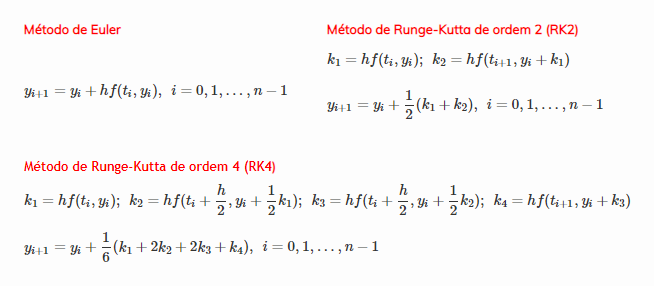

syms u(t) v(t)

f =@(t,u,v) v;
g =@(t,u,v) -16*u;
a = 0;
b = 4;
n = 100;
u0 = 9;
v0 = 0;

eqns = [diff(u,t,1)==v,diff(v,t,1)==-16*u];
ci = [u(0)==u0,v(0)==v0];
[sExataU,sExataV] =dsolve(eqns,ci);

h = @(t) eval(vectorize(char(sExataU)));

[t,uEuler,~] = NEulerSED(f,g,a,b,n,u0,v0);
[~,uRK4,~] = NRK4SED(f,g,a,b,n,u0,v0);

uExata = h(t)

uExata =     9.0000    8.8850    8.5431    7.9830    7.2189    6.2704    5.1617    3.9211    2.5804    1.1738   -0.2628   -1.6927   -3.0793   -4.3873   -5.5833   -6.6365   -7.5203   -8.2119   -8.6938   -8.9536   -8.9847   -8.7862   -8.3633   -7.7267   -6.8928   -5.8828   -4.7225   -3.4416   -2.0727   -0.6509    0.7875    2.2058    3.5678    4.8386    5.9858    6.9801    7.7961    8.4129    8.8149    8.9916    8.9387    8.6574    8.1549    7.4442    6.5432    5.4752    4.2672    2.9503    1.5579    0.1258



erroEuler = abs(uExata-uEuler);
erroRK4 = abs(uExata-uRK4);

array2table([t.',uExata.',uEuler.',uRK4.',erroEuler.',erroRK4.'],"VariableNames",{'t','Exata','Euler','RK4','erroEuler','erroRK4'})

ans = 101×6 table
     t       Exata      Euler       RK4       erroEuler     erroRK4  
    ____    _______    _______    ________    _________    __________

       0          9          9           9           0              0
    0.04      8.885          9       8.885     0.11495     2.0962e-07
    0.08     8.5431     8.7696      8.5431     0.22648     2.9182e-06
    0.12      7.983     8.3088       7.983     0.32585     8.0139e-06
    0.16     7.2189     7.6235      7.2189     0.40464     1.5261e-05
     0.2     6.2704     6.7255      6.2704     0.45513     2.4309e-05
    0.24     5.1617     5.6323      5.1617     0.47064     3.4705e-05
    0.28     3.9211      4.367      3.9212     0.44584     4.5911e-05
    0.32     2.5804     2.9575      2.5805     0.37702     5.7325e-05
    0.3

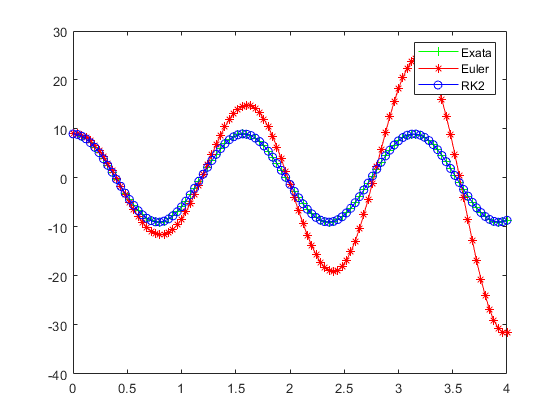


plot(t,uExata,"-g+")
hold on
plot(t,uEuler,"-r*")
plot(t,uRK4,"-bo")
hold off
legend("Exata","Euler","RK4")